##   Oceanus - Test Frame Search Process

Author: Michel Barbeau, Carleton University

Draft version: March 21, 2021

### Read wave file

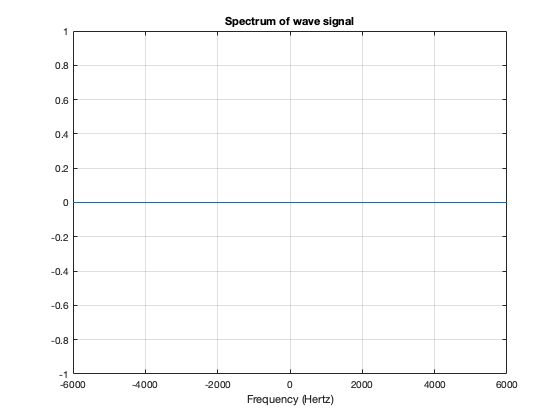

clear;
% Mode index (1..6)
mode = 1;
% Frame search interval vs mode (minutes)
interval = [1 2 4 8 16 20];
% samples per symbol vs mode
spsymbol = [128 256 512 1024 2048 2560];
% input wave file
WavFileName = "209_12000_"+int2str(mode)+".wav";
% OK
% WavFileName = "Ahmad20minutes/test.wav";
% ?
% WavFileName = "Ahmad20minutes/test_SNR_-25.wav";
% Center Frequency (Hertz)
cf = 209;
%%%% Arctic 2012 Data
% Originaly, the signal had been recorded at carrier frequency is 360 Hz at 4,500 sps.
% When it was replaid during the sea trial (August 2019), the signal has been re-sampled [Stephane] 
% with an interpolation on factor off 22, taking it to 22 * 4,500 = 99,000 sps.
% The signals had been played at 100,000 sps [Stephane], accelerating them by a factor of 100/99.
%
% A rational resampler (Interpolation: 8, Decimination: 5) resample from 5,000 sps to 8,000 sps. 
% A correction is added, due to accelerated playback: 100/99 * 360 Hz = 4 Hz.
% Center Frequency is set to 364 Hz.
% Half bandwidth (Hertz)
hb = 10;
%%% Plot the data in the frequency domain ("fs" is sample rate)
[x,fs] = audioread(WavFileName);
% % keep the 1st "interval(mode)" minutes
x = x(1:interval(mode)*fs*60); % keep the following "interval(mode)"  minutes
% x = x';
FFTSIZE=fs;
N=length(x); % number of sambles (interval(mode)*60 seconds of signal)
y=fft(x,FFTSIZE)/FFTSIZE; % FFT
figure; 
% plot(f,abs([y(N/2+1:N)', y(1:N/2)']));
plot([-FFTSIZE/2:1:-1 0:1:FFTSIZE/2-1], abs([y(FFTSIZE/2+1:FFTSIZE)', y(1:FFTSIZE/2)']));
title('Spectrum of wave signal');
xlabel("Frequency (Hertz)");
grid on

Downconversion to baseband (complex envolop).

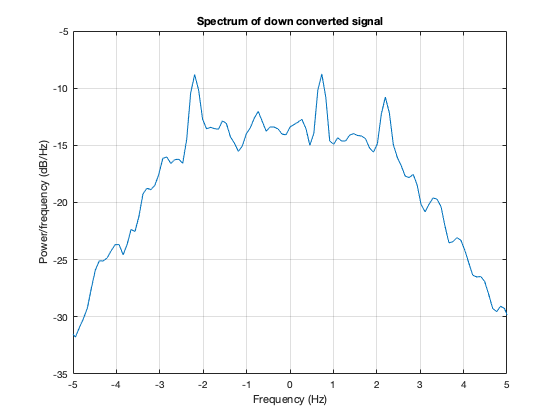

% for the files "209_12000_"+int2str(mode)+".wav";
dwnConv = dsp.DigitalDownConverter(...
  'DecimationFactor',32,... % yields 45000 samples (375 sps * 120 s)
  'SampleRate', fs,...
  'Bandwidth', 187,...
  'StopbandAttenuation', 55,...
  'PassbandRipple',0.2,...
  'CenterFrequency',cf); % frequency translation offset
  
% plot the spectrum
xDown = dwnConv(x); % down convert
window = hamming(floor(length(xDown)/10));
figure; pwelch(xDown,window,[],[],fs/32,'centered');
title('Spectrum of down converted signal');
xlim([-5 5])

% visualizeFilterStages(dwnConv);